Филимонов Степан РЛ6-31

Лабараторная номер 6

Задача:

Моделирование движение частицы в свободном пространстве в положительноч направлении оси х. 

Фото задания:

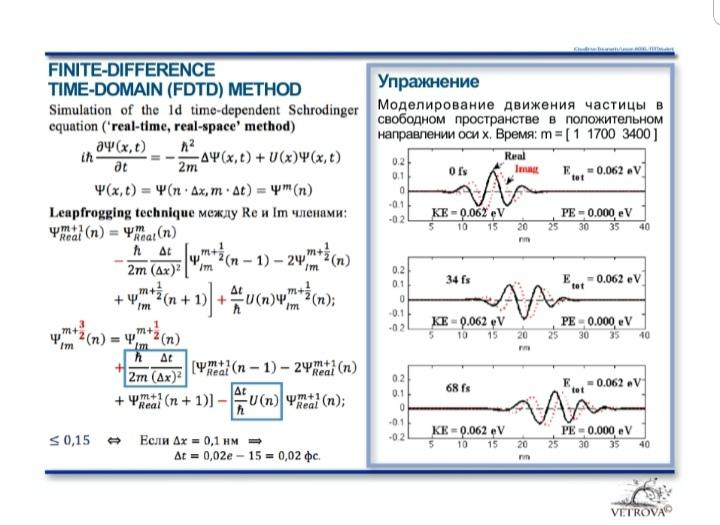

Решение:

Задание 1:

Тестовое задание:

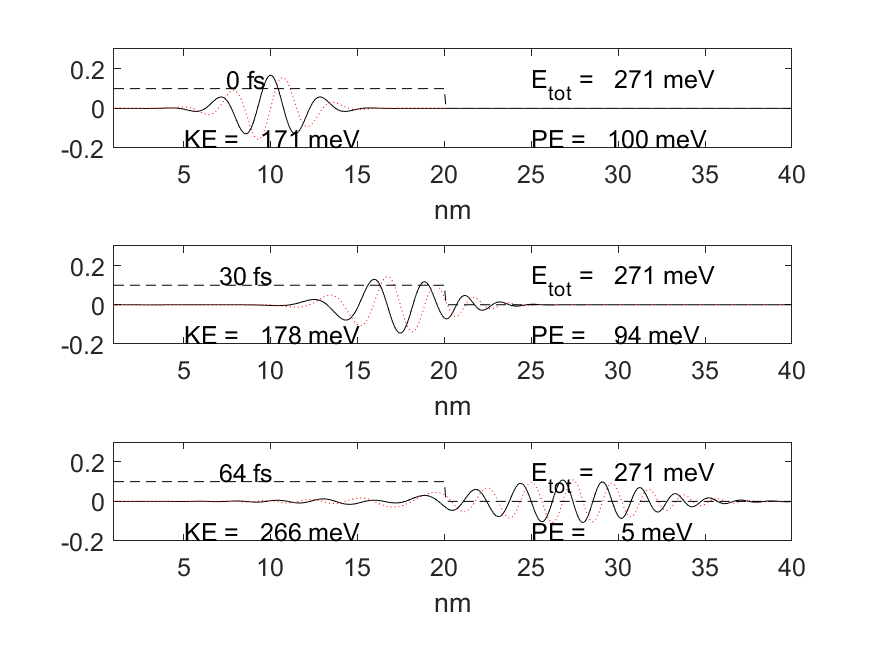

Код Matlab:

cla reset;
hold on;
load("constans.mat");

- **Константы и значения**

i = sqrt(-1);
Np = 400;  % Количество точек в проблемном пространстве Np = 400;
%5Np = 250;
T = 0;
Nstep=1;
time = [1 1500 1700]; % 1 1699 1700
meff = 1;  % эффективная масс: Si is 1.08, Ge is 0.067, GaAs is 0.55
m = meff * m0;  % Масса электрона
dx = 0.1e-9; % Размер ячейки dx = 0.1e-9;
%dx = 0.2e-9;
dt = 2e-17; % Временные шаги dt = 0.2e-17;
%dt = 1e-16;


$$\textrm{ra}=\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }$$


ra = (hbar / (2 * m)) * (dt /(dx)^2)  % Коэфицент номер 1, должен быть меньше < 0.15

ra = 0.1158

ra < 0.15 -> возможна связь

DX = dx * 1e9;  % Целое колличество нм
XX = (1:Np) * DX; % Длина в нм для построения графика            
Dsquared = (diag(ones(1,Np-1),1) - 2 * diag(ones(1,Np)) + diag(ones(1,Np-1),-1));  % диагональ 1 -2 1

- **Потенциал**

V = zeros(1,Np)'; % 0..- => ' => 0|.. вертикальной сделает  
V = [zeros(1,Np/2) + 0.1 zeros(1,Np/2)]'*eV2J; % половина нули половина eV2J

- **Инициализируем синусоидальную волну в гауссовой огибающей**

lambda = 30;  % Длина волны импульса
lamda_test = lambda * dx * 1e9

lamda_test = 3

sigma = 20;  % Ширина импульса
nc = 100;  % Исходное положение 150
n=(1:Np)';


$$P=e^{-\frac{{\left(n-\textrm{исходное}\;\textrm{положение}\right)}^2 }{2*\textrm{ширина}\;{\textrm{импульса}}^2 }} *\left(\cos \left(2\pi \frac{n-\textrm{исходное}\;\textrm{положение}}{\textrm{длина}\;\textrm{волны}}\right)+i*\sin \left(2\pi \frac{n-\textrm{исходное}\;\textrm{положение}}{\textrm{длина}\;\textrm{волны}}\right)\right)$$


Pulse = exp(-0.5*((n-nc)/sigma).^2).*(cos(2*pi*(n-nc)/lambda) + i*sin(2*pi*(n-nc)/lambda));
PulseReal = real(Pulse); % Реальня часть импульса
PulseImag = imag(Pulse); % Мнимая часть импульса
PulseZ = PulseReal + i*PulseImag; % И мнимая и реальная часть импульса

- **Нормируем её и проверяем**


$$N=\frac{\overrightarrow{n} }{\left|\overrightarrow{n} \right|}$$


PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)));  % Константа нормализации
PulseReal = PulseReal / PulseNormal;
PulseImag = PulseImag / PulseNormal;
PulseZ = PulseReal + i*PulseImag; 
control = sqrt(sum(PulseZ.*conj(PulseZ)));
PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)))  % Константа нормализации

PulseNormal = 1

- **PDTD**

for n_step = 1:3    

- **Главные вычисления**

    for mm=1:time(n_step)
        T = T + 1;


$$\Psi_{\textrm{Real}} \left(n\right)=\Psi_{\textrm{Real}}^m \left(n\right)-\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }*\Psi_{\textrm{Imag}} \left\lbrack \left(n-1\right)-2*\left(n\right)+\left(n+1\right)\right\rbrack \;+\;\frac{\Delta t}{\hbar }U\left(n\right)\Psi_{\textrm{Imag}} \;$$


        PulseReal = PulseReal - ra*Dsquared*PulseImag + (dt/hbar)*V.*PulseImag;        


$$\Psi_{\textrm{Imag}} \left(n\right)=\Psi_{\textrm{Imag}}^m \left(n\right)+\;\frac{\hbar }{2m}*\frac{\Delta t}{{\left(\Delta x\right)}^2 }*\Psi_{\textrm{Real}} \left\lbrack \left(n-1\right)-2*\left(n\right)+\left(n+1\right)\right\rbrack -\;\frac{\Delta t}{\hbar }U\left(n\right)\Psi_{\textrm{Real}} \;$$


        PulseImag = PulseImag + ra*Dsquared*PulseReal - (dt/hbar)*V.*PulseReal;
    end
    subplot(3,1,Nstep)
    plot(XX,PulseReal,'k',"Color","black") 
    hold on
    plot(XX,PulseImag,':k',"Color","red")
    plot(XX,J2eV*V,'--k') % потенциальная энерги 
    hold off
    axis( [ 1 DX*Np -0.2 0.3 ])
    xlabel('nm')
    set(gca,'fontsize',12)
    Nstep=Nstep+1;

- **Подписываем график**

    % ------- Проверяем нормализацию -----------------
    PulseZ = PulseReal+i*PulseImag; 
    PulseZ'*PulseZ 
    PulseNormal = sqrt(sum(PulseZ.*conj(PulseZ)));
    % ------- Вычислите ожидаемые значения ------------
    KE = J2eV * real(-(hbar/dx)^2/(2*m)*PulseZ'*(Dsquared*PulseZ)) *1e3; % Кинетическая энергия
    PE = J2eV * PulseZ' * (V.*PulseZ)*1e3; % Потенциальная энергия
    TT = text(5,.15,sprintf('%7.0f fs',T*dt*1e15));
    set(TT,'fontsize',12)
    TT = text(5,-.15,sprintf('KE = %5.0f meV',KE));
    set(TT,'fontsize',12)
    TT = text(25,-.15,sprintf('PE = %5.0f meV',PE));
    set(TT,'fontsize',12)
    TT = text(25,.13,sprintf('E_t_o_t = %5.0f meV',KE+PE));
    set(TT,'fontsize',12)

- **Сохраняем график**

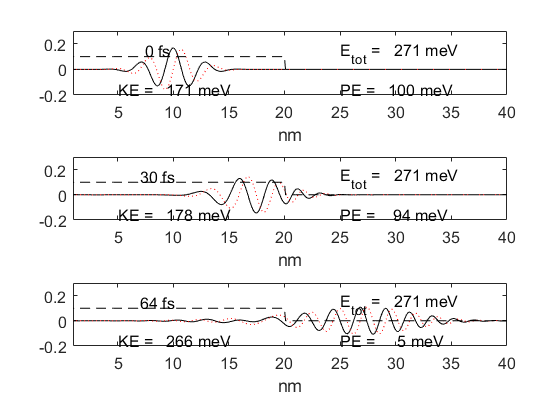

ans = 1.0000

ans = 1.0000

ans = 1.0000

    % saveas(gcf,'test.png')      % This saves the picture to a file
end

- **Время:**

datetime('now')

ans = datetime
   16-Dec-2021 11:05:23
